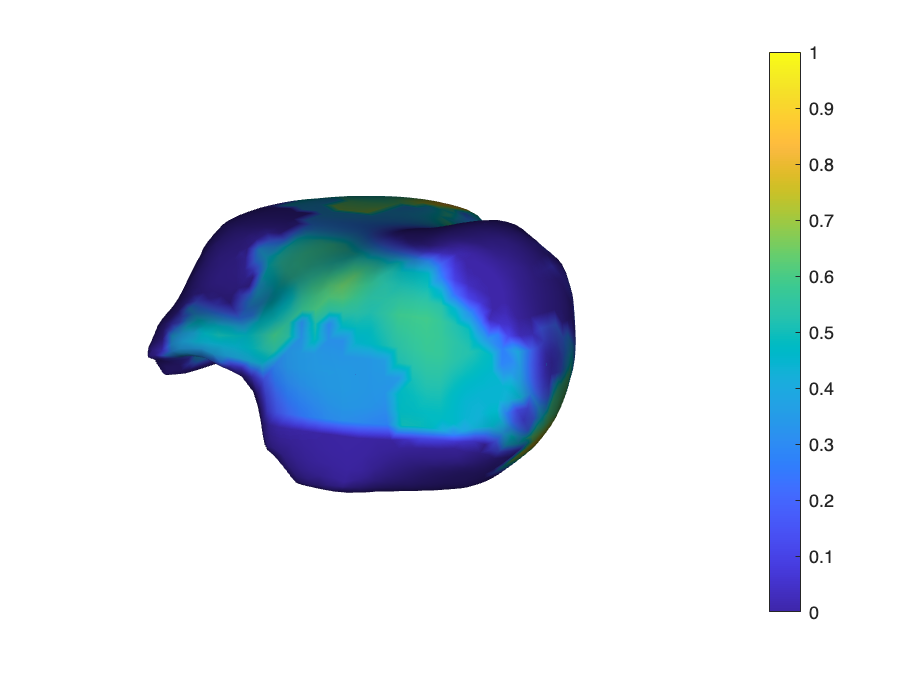

% T1 * Mask normalized by T1
% Load data
% nii_t1 = double(niftiread('Anonymous_59/0 Anonymous_59.nii.gz'));
% nii_mask = niftiread('Anonymous_59/0 Anonymous_59_Segmentation.nii.gz');

% nii_t1 = double(niftiread('Anonymous_48/0 Anonymous_48.nii.gz'));
% nii_mask = niftiread('Anonymous_48/0 Anonymous_48_Segmentation.nii.gz');

% nii_t1 = double(niftiread('IA_103_A1/IA_103_A1_T1.nii.gz'));
% nii_t1gd = double(niftiread('IA_103_A1/IA_103_A1_T1Gd.nii.gz'));
% nii_mask = niftiread('IA_103_A1/IA_103_A1_label.nii.gz');

nii_t1 = double(niftiread('RJ_009_A0/RJ_009_A0_T1.nii.gz'));
nii_t1gd = double(niftiread('RJ_009_A0/RJ_009_A0_T1Gd.nii.gz'));
nii_mask = niftiread('RJ_009_A0/RJ_009_A0_label(1).nii.gz');
% nii_mask = niftiread('RJ_009_A0/RJ_009_A0_pred.nii.gz');

% nii_t1 = double(niftiread('Anonymous_55/0 Anonymous_55.nii.gz'));
% % nii_mask = niftiread('Anonymous_55/0 Anonymous_55_Segmentation.nii.gz');
% nii_mask = niftiread('Anonymous_55/0 Anonymous_55_Segmentation-blood-label.nii.gz');

% T1 * mask
masked_img = nii_t1 .* double(nii_mask);

% lumen: dark region
lumen_threshold = 0.3 * max(masked_img(:));  % ~30% of max
lumen_mask = masked_img < lumen_threshold;

% Wall mask = label - lumen
wall_mask = nii_mask & ~lumen_mask;

% Create surface from wall mask
fv = isosurface(wall_mask, 0.5);
fv = smoothpatch(fv, 1, 10);  % smoothing

% Normalize masked T1 by max T1
max_t1 = max(nii_t1(nii_mask > 0));
nii_t1_norm = masked_img / max_t1;

% Normalize masked T1 by max T1gd
% max_t1gd = max(nii_t1gd(nii_mask > 0));
% nii_t1_norm = masked_img / max_t1gd;


% Interpolator for normalized T1
[x, y, z] = ndgrid(1:size(nii_t1_norm,1), 1:size(nii_t1_norm,2), 1:size(nii_t1_norm,3));
interpFunc = griddedInterpolant(x, y, z, nii_t1_norm, 'linear', 'nearest');

% Compute normals
normals = isonormals(double(wall_mask), fv.vertices);

% Sample SI along normals
max_sis = zeros(size(fv.vertices, 1), 1);
step = 0.1;
for i = 1:size(fv.vertices, 1)
    vertex = fv.vertices(i,:);
    normal = normals(i,:) / (norm(normals(i,:)) + eps);

    sis = [];
    for t = 0:step:1.2
        sample_point = vertex + t * normal;
        sis(end+1) = interpFunc(sample_point(1), sample_point(2), sample_point(3));
    end
    max_sis(i) = max(sis);
end



% Visualize
figure;
trisurf(fv.faces, fv.vertices(:,1), fv.vertices(:,2), fv.vertices(:,3), ...
    max_sis, ...
    'FaceColor', 'interp', 'EdgeColor', 'none');
colormap parula;
colorbar;
clim([0 1]); 
axis equal;
axis off;
% view(3);

% Anonymous 28
% view(230, 20);

% IA103
view(30, 10);

lighting gouraud;
camlight headlight;
material dull;

% title('T1 * Label normalized by max(T1)');


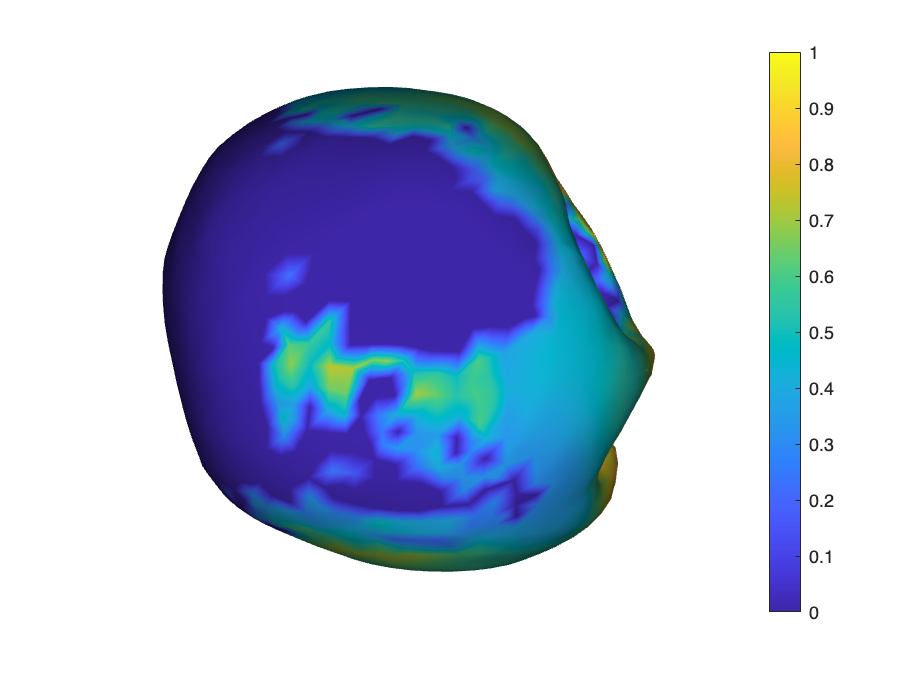

% T1 * Mask normalized by T1
% Load data
% nii_t1 = double(niftiread('Anonymous_59/0 Anonymous_59.nii.gz'));
% nii_mask = niftiread('Anonymous_59/0 Anonymous_59_Segmentation.nii.gz');

% nii_t1 = double(niftiread('Anonymous_48/0 Anonymous_48.nii.gz'));
% nii_mask = niftiread('Anonymous_48/0 Anonymous_48_Segmentation.nii.gz');

nii_t1 = double(niftiread('IA_103_A1/IA_103_A1_T1.nii.gz'));
nii_t1gd = double(niftiread('IA_103_A1/IA_103_A1_T1Gd.nii.gz'));
nii_mask = niftiread('IA_103_A1/IA_103_A1_label.nii.gz');

% nii_t1 = double(niftiread('Anonymous_55/0 Anonymous_55.nii.gz'));
% % nii_mask = niftiread('Anonymous_55/0 Anonymous_55_Segmentation.nii.gz');
% nii_mask = niftiread('Anonymous_55/0 Anonymous_55_Segmentation-blood-label.nii.gz');

% T1 * mask
masked_img = nii_t1gd .* double(nii_mask);

% lumen: dark region
lumen_threshold = 0.3 * max(masked_img(:));  % ~30% of max
lumen_mask = masked_img < lumen_threshold;

% Wall mask = label - lumen
wall_mask = nii_mask & ~lumen_mask;

% Create surface from wall mask
fv = isosurface(wall_mask, 0.5);
fv = smoothpatch(fv, 1, 10);  % smoothing

% Normalize masked T1 by max T1
max_t1 = max(nii_t1gd(nii_mask > 0));
nii_t1_norm = masked_img / max_t1;

% Normalize masked T1 by max T1gd
% max_t1gd = max(nii_t1gd(nii_mask > 0));
% nii_t1_norm = masked_img / max_t1gd;


% Interpolator for normalized T1
[x, y, z] = ndgrid(1:size(nii_t1_norm,1), 1:size(nii_t1_norm,2), 1:size(nii_t1_norm,3));
interpFunc = griddedInterpolant(x, y, z, nii_t1_norm, 'linear', 'nearest');

% Compute normals (direction may be inconsistent, but we'll sample BOTH sides)
normals = isonormals(double(wall_mask), fv.vertices);

% Interpolator for wall mask (so we can constrain sampling to wall only)
interpWall = griddedInterpolant(x, y, z, double(wall_mask), 'nearest', 'nearest');

% Sample SI along normals (SYMMETRIC + constrained to wall)
max_sis = zeros(size(fv.vertices, 1), 1);
step  = 0.1;   % voxel step (your vertices are in voxel index space)
max_d = 3.0;   % sample radius in voxels (±3 voxels around the surface point)

sz = size(nii_t1_norm);

for i = 1:size(fv.vertices, 1)
    vertex = fv.vertices(i,:);
    n = normals(i,:);
    n = n / (norm(n) + eps);

    sis = [];

    for t = -max_d:step:max_d
        p = vertex + t * n;

        % bounds check (avoid extrapolation surprises)
        if any(p < 1) || p(1) > sz(1) || p(2) > sz(2) || p(3) > sz(3)
            continue;
        end

        % only sample inside wall
        if interpWall(p(1), p(2), p(3)) < 0.5
            continue;
        end

        sis(end+1) = interpFunc(p(1), p(2), p(3));
    end

    if isempty(sis)
        max_sis(i) = 0;          % or NaN if you prefer
    else
        max_sis(i) = max(sis);   % keep your original "max projection" intent
        % max_sis(i) = mean(sis); % <- if you want mean instead of max
    end
end

% Visualize
figure;
trisurf(fv.faces, fv.vertices(:,1), fv.vertices(:,2), fv.vertices(:,3), ...
    max_sis, ...
    'FaceColor', 'interp', 'EdgeColor', 'none');
colormap parula;
colorbar;
clim([0 1]); 
axis equal;
axis off;
% view(3);

% Anonymous 28
% view(230, 20);

% IA103
view(-80, 10);

lighting gouraud;
camlight headlight;
material dull;

% title('T1 * Label normalized by max(T1)');

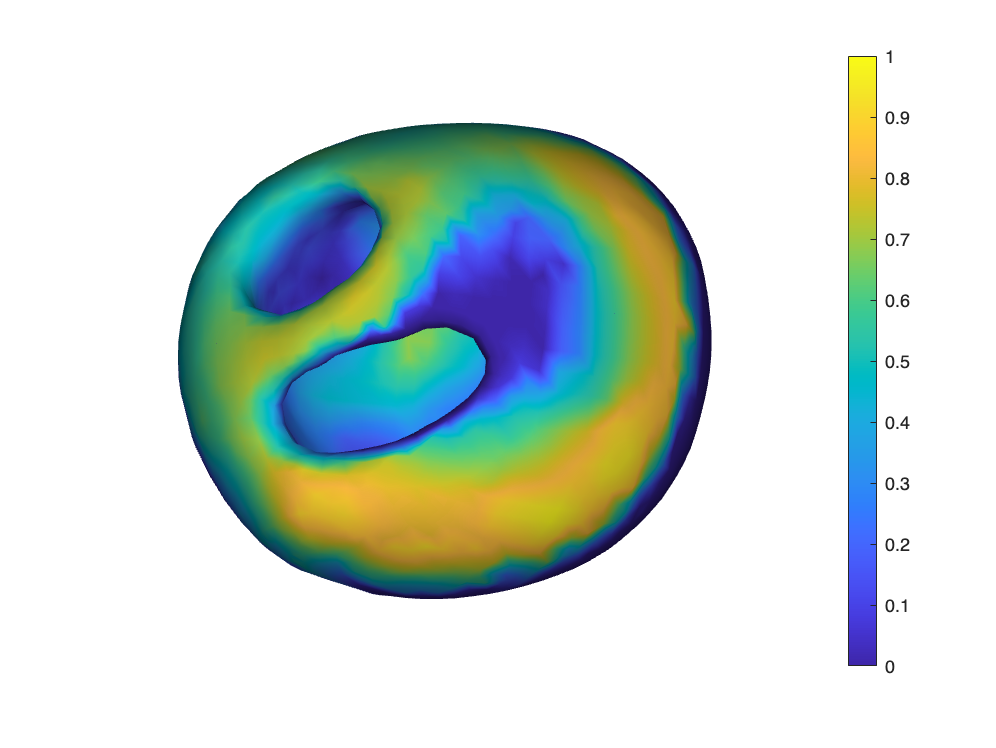

% T1 * Prediction normalized by T1GD
% Load data
% nii_t1 = double(niftiread('RJ_009_A0/RJ_009_A0_T1.nii.gz'));
% nii_mask = niftiread('RJ_009_A0/RJ_009_A0_pred.nii.gz');

nii_t1 = double(niftiread('IA_103_A1/IA_103_A1_T1.nii.gz'));
nii_t1gd = double(niftiread('IA_103_A1/IA_103_A1_T1Gd.nii.gz'));
nii_mask = niftiread('IA_103_A1/IA_103_A1_pred.nii.gz');

% T1 * mask
masked_img = nii_t1 .* double(nii_mask);

% lumen: dark region
lumen_threshold = 0.3 * max(masked_img(:));  % ~30% of max
lumen_mask = masked_img < lumen_threshold;

% Wall mask = label - lumen
wall_mask = nii_mask & ~lumen_mask;

% Create surface from wall mask
fv = isosurface(wall_mask, 0.5);
fv = smoothpatch(fv, 1, 10);  % smoothing

% Normalize masked T1 by max T1
max_t1 = max(nii_t1(nii_mask > 0));
nii_t1_norm = masked_img / max_t1;

% Normalize masked T1 by max T1gd
% max_t1gd = max(nii_t1gd(nii_mask > 0));
% nii_t1_norm = masked_img / max_t1gd;

% Interpolator for normalized T1
[x, y, z] = ndgrid(1:size(nii_t1_norm,1), 1:size(nii_t1_norm,2), 1:size(nii_t1_norm,3));
interpFunc = griddedInterpolant(x, y, z, nii_t1_norm, 'linear', 'nearest');

% Compute normals
normals = isonormals(double(wall_mask), fv.vertices);

% Sample SI along normals
max_sis = zeros(size(fv.vertices, 1), 1);
step = 0.1;
for i = 1:size(fv.vertices, 1)
    vertex = fv.vertices(i,:);
    normal = normals(i,:) / (norm(normals(i,:)) + eps);

    sis = [];
    for t = 0:step:1.2
        sample_point = vertex + t * normal;
        sis(end+1) = interpFunc(sample_point(1), sample_point(2), sample_point(3));
    end
    max_sis(i) = max(sis);
end

% Visualize
figure;
trisurf(fv.faces, fv.vertices(:,1), fv.vertices(:,2), fv.vertices(:,3), ...
    max_sis, ...
    'FaceColor', 'interp', 'EdgeColor', 'none');
colormap parula;
colorbar;
clim([0 1]); 
axis equal;
axis off;
% view(3);
view(50, -10);
lighting gouraud;
camlight headlight;
material dull;

% title('T1 * Prediction normalized by max(T1)');